img = imread('right9.jpg');
bwImg = rgb2gray(img);
%sobel kernel
kernel = [-1 0 1;
          -2 0 2;
          -1 0 1]

kernel =     -1     0     1
    -2     0     2
    -1     0     1


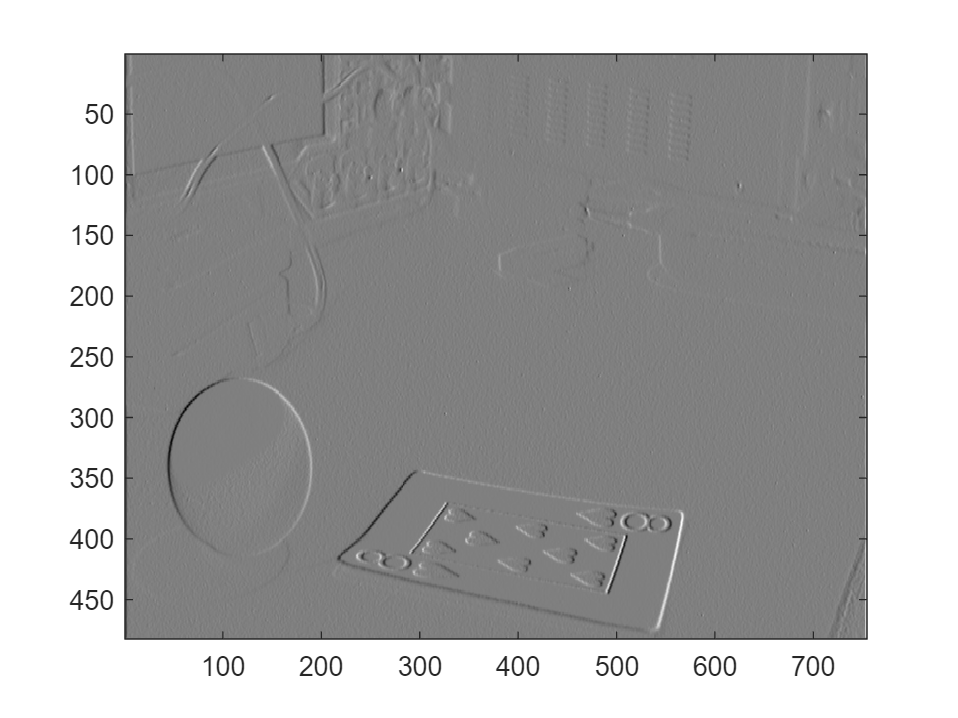

%push kernel across image to adjust it
%convolution of a larger image by a smaller kernel results in a smaller
%image; we can pad the image if we want to maintain size
convolvedImg = conv2(bwImg,kernel);
colormap gray
imagesc(convolvedImg)

%kernel = [1 1 1;
%          1 1 1;
%          1 1 1];
% 3x3 = 9 so we divide by point 9 to normalize the filter
%kernel = kernel/0.9; 

kernel = ones(10,10);
kernel = kernel./100;
%push kernel across image to adjust it
%convolution of a larger image by a smaller kernel results in a smaller
%image; we can pad the image if we want to maintain size
convolvedImg = conv2(bwImg,kernel);
colormap gray

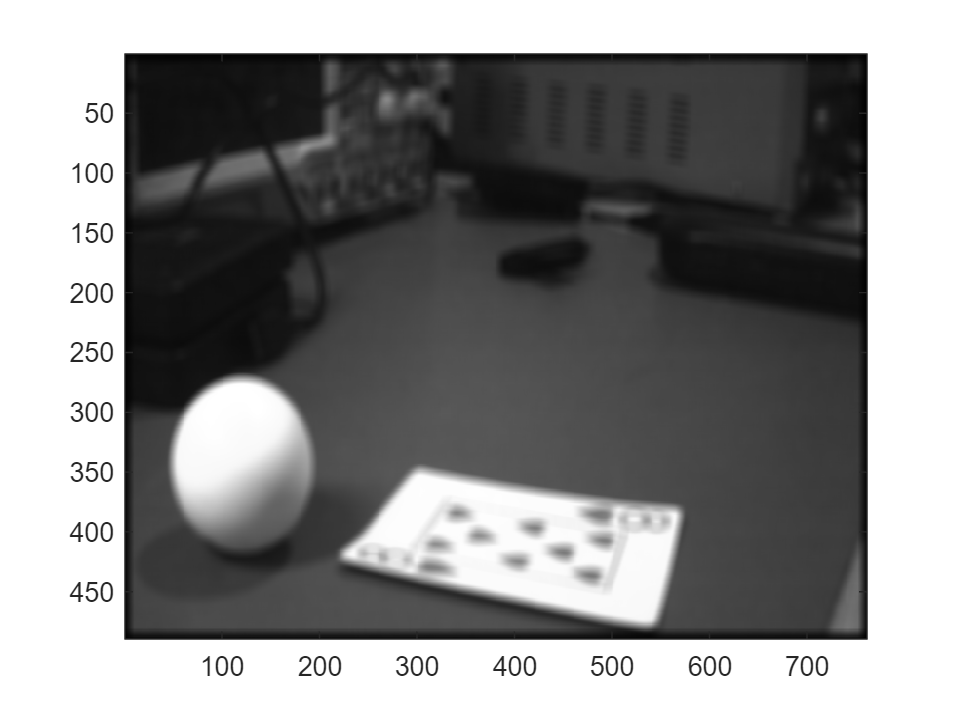

imagesc(convolvedImg)